I1 = imread('left.jpeg');
I2 = imread('right.jpeg');

% Convert to grayscale.
I1gray = rgb2gray(I1);
I2gray = rgb2gray(I2);

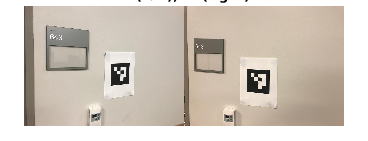

figure;
imshowpair(I1, I2,'montage');
title('I1 (left); I2 (right)');

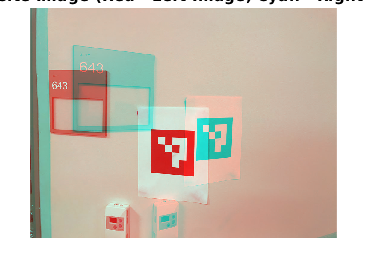

figure;
imshow(stereoAnaglyph(I1,I2));
title('Composite Image (Red - Left Image, Cyan - Right Image)');

blobs1 = detectSURFFeatures(I1gray, 'MetricThreshold', 2000);
blobs2 = detectSURFFeatures(I2gray, 'MetricThreshold', 2000);

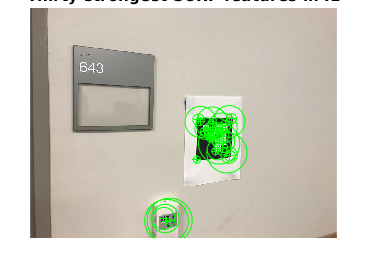

figure;
imshow(I1);
hold on;
plot(selectStrongest(blobs1, 30));
title('Thirty strongest SURF features in I1');

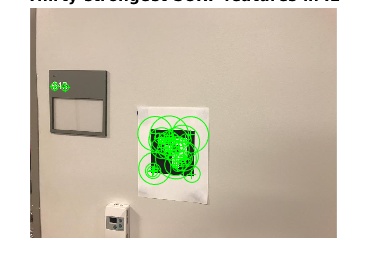


figure;
imshow(I2);
hold on;
plot(selectStrongest(blobs2, 30));
title('Thirty strongest SURF features in I2');

[features1, validBlobs1] = extractFeatures(I1gray, blobs1);
[features2, validBlobs2] = extractFeatures(I2gray, blobs2);

indexPairs = matchFeatures(features1, features2, 'Metric', 'SAD', ...
  'MatchThreshold', 5);

matchedPoints1 = validBlobs1(indexPairs(:,1),:);
matchedPoints2 = validBlobs2(indexPairs(:,2),:);

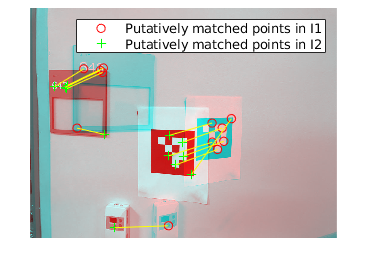

figure;
showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2);
legend('Putatively matched points in I1', 'Putatively matched points in I2');

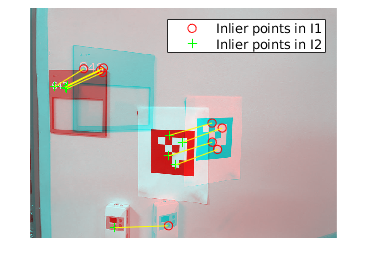

[fMatrix, epipolarInliers, status] = estimateFundamentalMatrix(...
  matchedPoints1, matchedPoints2, 'Method', 'RANSAC', ...
  'NumTrials', 100, 'DistanceThreshold', 0.1, 'Confidence', 99.99);

if status ~= 0 || isEpipoleInImage(fMatrix, size(I1)) ...
  || isEpipoleInImage(fMatrix', size(I2))
  error(['Either not enough matching points were found or '...
         'the epipoles are inside the images. You may need to '...
         'inspect and improve the quality of detected features ',...
         'and/or improve the quality of your images.']);
end

inlierPoints1 = matchedPoints1(epipolarInliers, :);
inlierPoints2 = matchedPoints2(epipolarInliers, :);

figure;
showMatchedFeatures(I1, I2, inlierPoints1, inlierPoints2);
legend('Inlier points in I1', 'Inlier points in I2');

[t1, t2] = estimateUncalibratedRectification(fMatrix, ...
  inlierPoints1.Location, inlierPoints2.Location, size(I2));
tform1 = projective2d(t1);
tform2 = projective2d(t2);

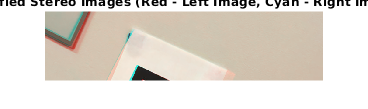

[I1Rect, I2Rect] = rectifyStereoImages(I1, I2, tform1, tform2);
figure;
imshow(stereoAnaglyph(I1Rect, I2Rect));
title('Rectified Stereo Images (Red - Left Image, Cyan - Right Image)');